close all;clc;clear;
handle  = OCTFileOpen('Default_0193_Mode2D.oct');
disp( OCTFileGetProperty(handle, 'AcquisitionMode') );

Mode2D


disp( OCTFileGetProperty(handle, 'RefractiveIndex') );

1.000000


disp( OCTFileGetProperty(handle, 'Comment') );
disp( OCTFileGetProperty(handle, 'Study') );

Default


disp( OCTFileGetProperty(handle, 'ExperimentNumber') );

193


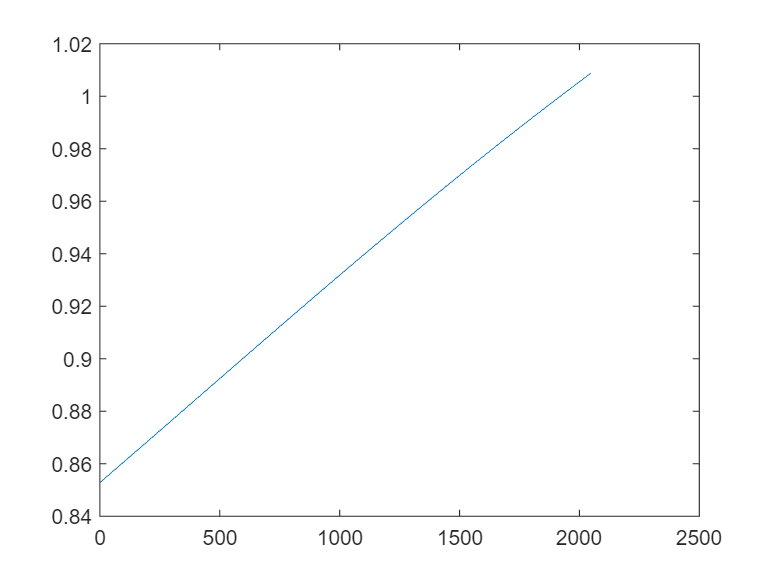

%-----------------------------------------------------------
%reading spectral raw data
NrRawData = OCTFileGetNrRawData(handle);
[RawData, Spectrum] = OCTFileGetRawData(handle, 0);
% plot(1:2048,RawData(:,1));

load('Wavelength.mat','Wavelength');
Wavelength = Wavelength';
plot(1:2048,Wavelength);

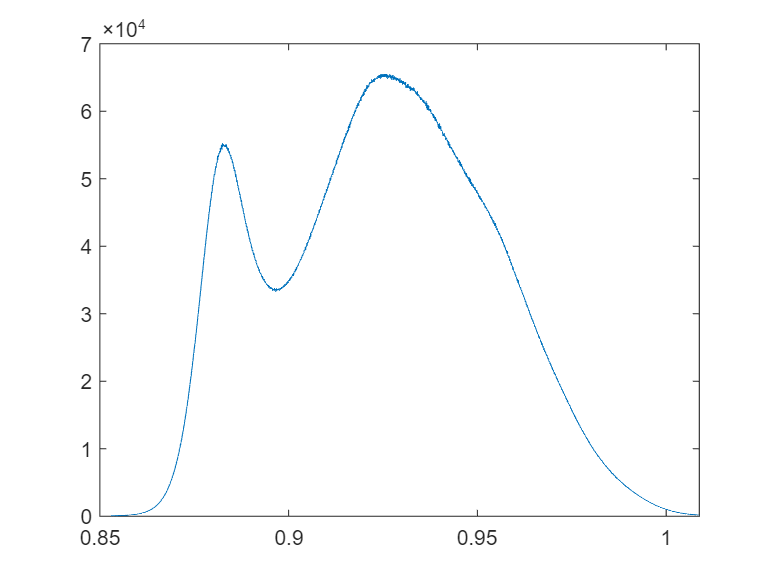

plot(Wavelength,Spectrum);

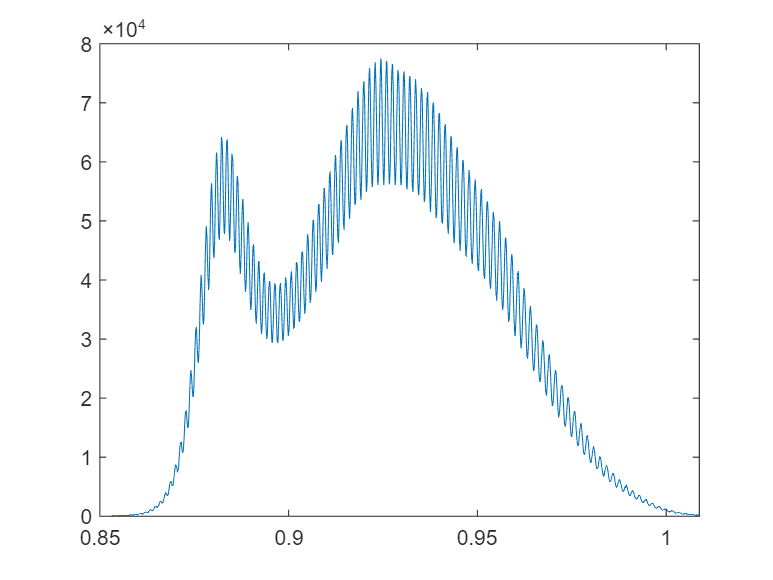

plot(Wavelength,RawData(:,1));

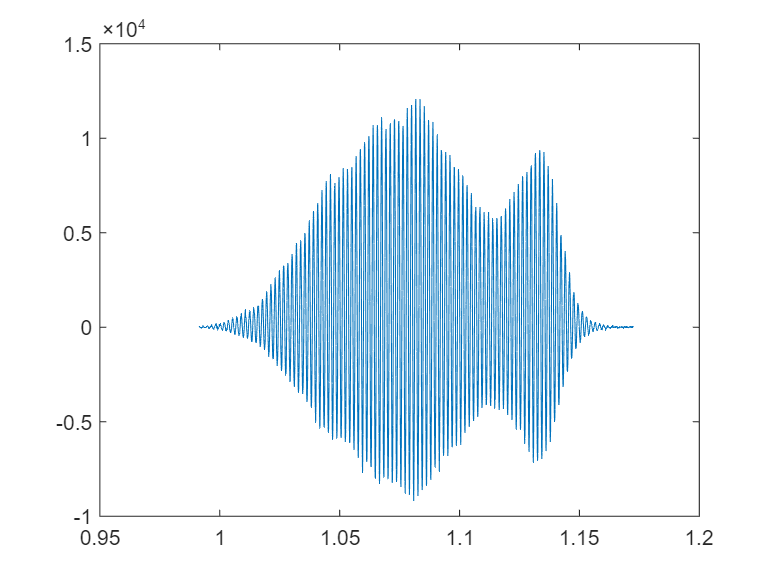

spectrum = RawData(:,1);
%消除直流项对ifft的影响
spectrum = spectrum - Spectrum;
%波数空间采样及线性矫正
%将波长和光谱强度逆序排列
intensity = zeros(1,length(spectrum));
wavelength = zeros(1,length(Wavelength));
for i = 1:length(Wavelength)
    wavelength(length(wavelength)+1-i) = Wavelength(i);
    intensity(length(intensity)+1-i) = spectrum(i);
end
%波长映射到波数
sigma = 1./wavelength;
%波数均匀采样
sigma_inter = linspace(sigma(1),sigma(end),length(sigma)); 
%光谱强度三次样条插值
intensity_inter = spline(sigma,intensity,sigma_inter);
plot(sigma_inter,intensity_inter);

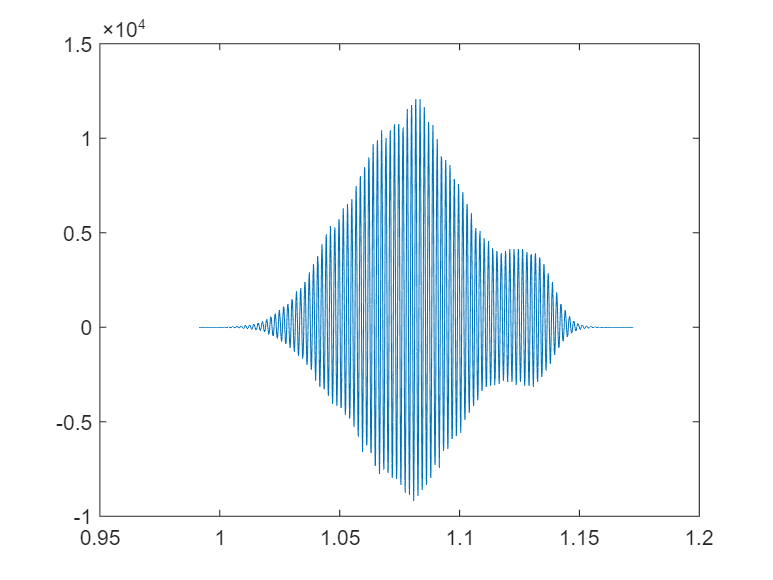

%干涉光谱整形（采用汉宁窗）
intensity_shaping = intensity_inter.* (hann(length(intensity_inter)))';
plot(sigma_inter,intensity_shaping);

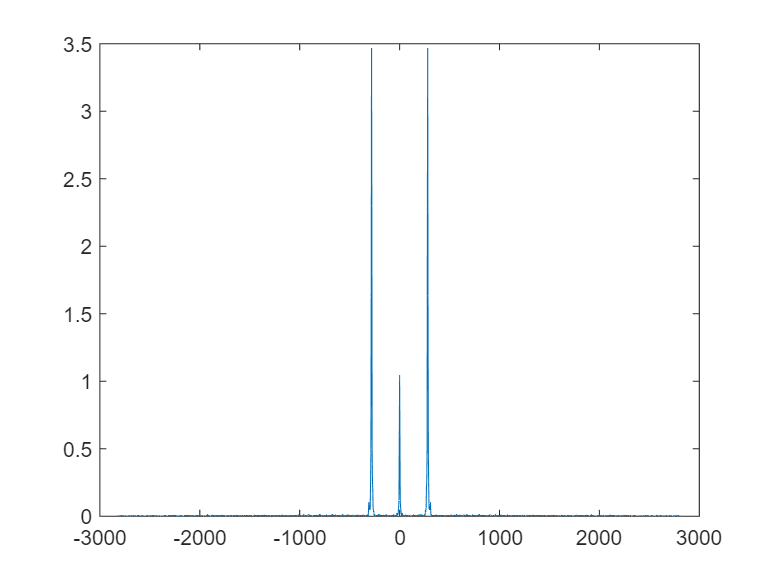

%对光谱进行傅里叶逆变换
Nifft = 2^20;
interference_signal = ifft(intensity_shaping,Nifft);
interference_signal = ifftshift(interference_signal);
deltaSigma = (sigma_inter(end)-sigma_inter(1))/(length(sigma_inter)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
z = (1:Nifft)*deltaZ;
intensity_ifft = abs(interference_signal);
%坐标变换
z = z-z(end)/2;
plot(z,intensity_ifft);